# Reproduction work 1--《多功能并网逆变器及其微电网应用_曾正》

Fonda Guo    2025/2

## Chapter 2

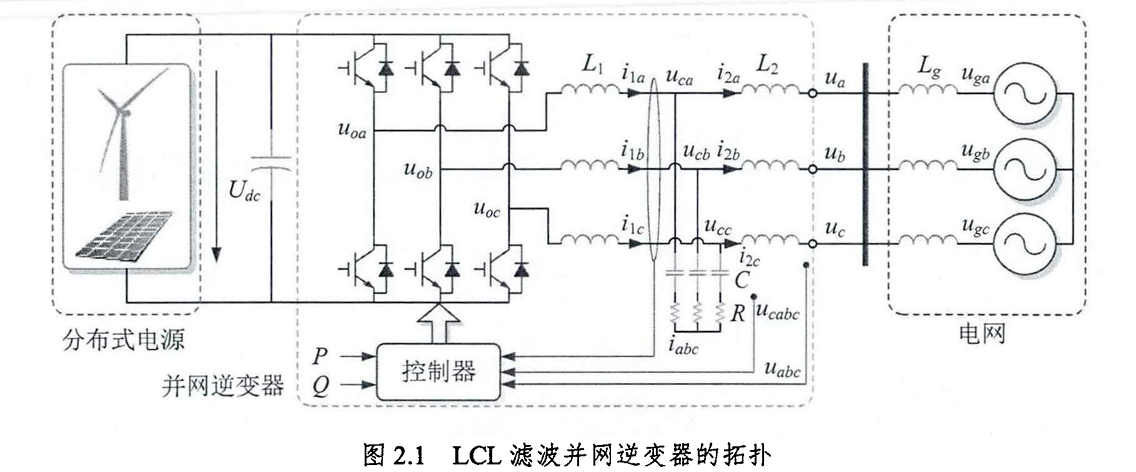

### 2.1 Basic Model


$$$$\left\{
\begin{array}{rcl}
L_{1}\dot{i}_{1a}=\left(s_{a}-\frac{1}{3}\sum_{k=a,b,c}s_{k}\right)U_{dc}-u_{ca}-R(i_{1a}-i_{2a})\\

L_{1}\dot{i}_{1b}=\left(s_{b}-\frac{1}{3}\sum_{k=a,b,c}s_{k}\right)U_{dc}-u_{cb}-R(i_{1b}-i_{2b})\\

L_{1}\dot{i}_{1c}=\left(s_{c}-\frac{1}{3}\sum_{k=a,b,c}s_{k}\right)U_{dc}-u_{cc}-R(i_{1c}-i_{2c})
\end{array}
\right.
$$$$
        
$$\begin{cases}L_{2}i_{2a}=u_{ca}+R(i_{1a}-i_{2a})-u_{a}\\L_{2}i_{2b}=u_{cb}+R(i_{1b}-i_{2b})-u_{b}\\L_{2}i_{2c}=u_{cc}+R(i_{1c}-i_{2c})-u_{c}&\end{cases}$$
   
$$\begin{cases}C\dot{u}_{ca}=i_{1a}-i_{2a}\\C\dot{u}_{cb}=i_{1b}-i_{2b}\\C\dot{u}_{cc}=i_{1c}-i_{2c}&\end{cases}$$


Clarke & Park Transformation


$$T_{abc/\alpha\beta0}=\sqrt{\frac{2}{3}}\left[\matrix{1&-1/2&-1/2\cr0&-\sqrt{3}/2&\sqrt{3}/2\cr\sqrt{2}/2&\sqrt{2}/2&\sqrt{2}/2}\right]$$
      
$${T}_{abc/dq0}=\sqrt{\frac{2}{3}}\left[\matrix{\cos\theta&\cos(\theta-2\pi/3)&\cos(\theta+2\pi/3)\cr-\sin\theta&-\sin(\theta-2\pi/3)&-\sin(\theta+2\pi/3)\cr\sqrt{2}/2&\sqrt{2}/2&\sqrt{2}/2}\right]$$


After transformation


$$\begin{cases}
\begin{array}{lcl}
L_{1}\dot{i}_{1d}=s_{d}U_{dc}-u_{cd}-R(i_{1d}-i_{2d})+\omega L_{1}i_{1q}\\
L_{1}\dot{i}_{1q}=s_{q}U_{dc}-u_{cq}-R(i_{1q}-i_{2q})-\omega L_{1}i_{1d}\\
L_{2}\dot{i}_{2d}=u_{cd}+R(i_{1d}-i_{2d})-u_{d}+\omega L_{2}i_{2q}\\
L_{2}\dot{i}_{2q}=u_{cq}+R(i_{1q}-i_{2q})-u_{q}-\omega L_{2}i_{2d}\\
C\dot{u}_{cd}=i_{1d}-i_{2d}+\omega Cu_{cq}\\
C\dot{u}_{cq}=i_{1q}-i_{2q}-\omega Cu_{cd}&
\end{array}
\end{cases}$$


## Chapter 5

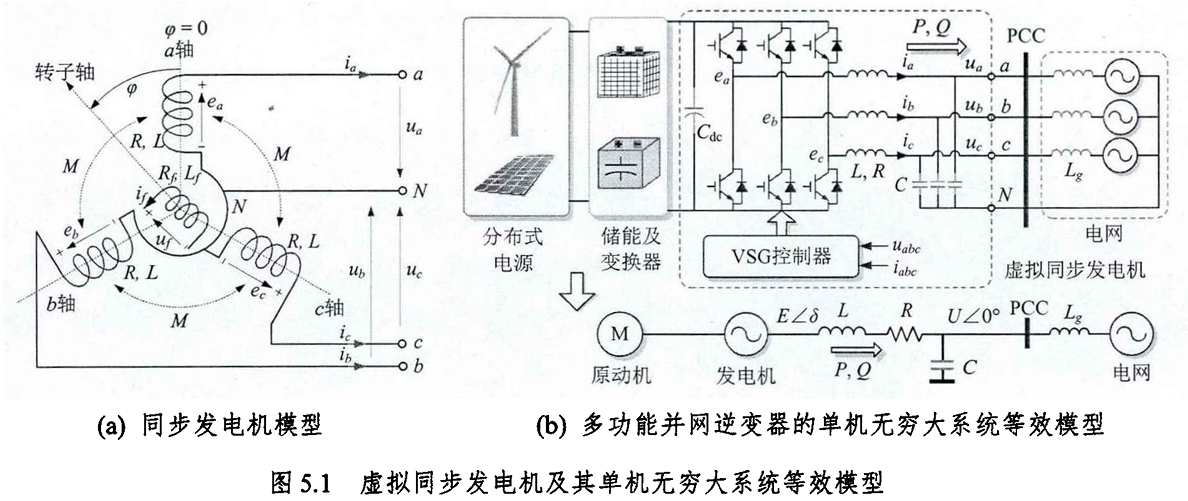 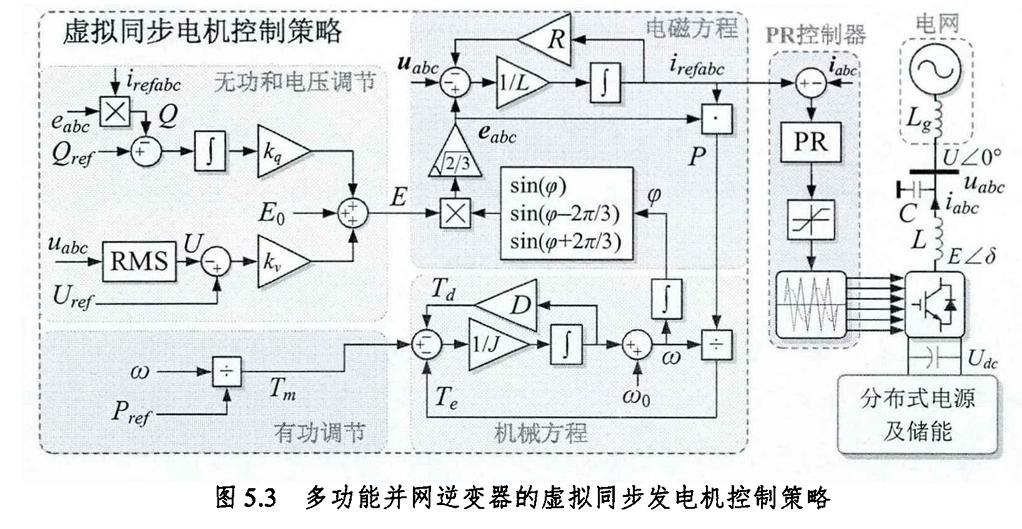

### 5.1 Mechenical equations:

Swing Equation


$$\begin{cases}\begin{array}{lcl}\dot{\delta}=\omega - \omega_0
\\J\dot{\omega}=T_m-T_e-T_d=T_m-T_e-D(\omega-\omega_0)&\end{array}\end{cases}\\
\quad Te = P/\omega = (e_ai_a + e_bi_b + e_ci_c)/\omega$$


Inertia Time Constant(Energy)


$$H = J\omega^2_0  /  S_n$$


Under Per-unit


$$\begin{cases}\begin{array}{lcl}
\dot{\delta}=\omega_0\omega_r
\\ H\dot\omega_r=T^*_m-T^*_e-D_p\omega_r \approx P^*_{ref}-P^*_e-D_p\omega_r
\end{array}\end{cases}\\$$


  where:


$$\begin{array}{lcl}
\omega_{r} = (\omega - \omega_0)/\omega_0\\
T_{Basic} = S_n/\omega_0,\quad T^*_m = T_m/T_{Basic},\quad T^*_e = T_e/T_{Basic}\\
D_p = D\omega^2_0/S_n
\end{array}$$


The approximation equation is saitisfied because J is large enough omega changes little and slow


$$\begin{array}{lcl}
\Delta T^* = (T^*_m - T^*_e)/T_{Basic} =  (T^*_m - T^*_e)\omega_0/S_n \approx (T^*_m\omega - T^*_e\omega_0)/S_n=(P_{ref} - P_e)/S_n = P^*_{ref} - P^*_e\\
\end{array}$$


### 5.2 Electrical equations:

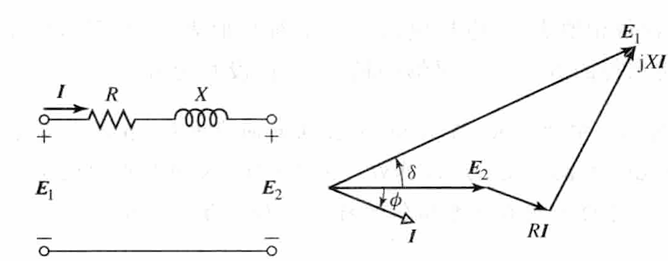


$$\dot{I} = \frac{E\angle\delta-U}{R + j\omega L}$$


So apparent power


$$\begin{array}{lcl}S&=U\dot{I}^{*}=U\frac{E\angle(-\delta)-U}{R-j\omega L}=\frac{EU\angle(-\delta)-U^{2}}{Z\angle(-\alpha)}=\frac{EU}{Z}\angle(\alpha-\delta)-\frac{U^{2}}{Z}\angle\alpha\\
&=\frac{EU}{Z}\cos(\alpha-\delta)+j\frac{EU}{Z}\sin(\alpha-\delta)-\frac{U^2}{Z}\cos\alpha-j\frac{U^2}{Z}\sin\alpha\\&=P+jQ\end{array}$$


where active and reactive power is


$$\begin{cases}
\begin{array}{lcl}
P = \frac{EU}{Z}cos(\alpha - \delta) - \frac{U^2}{Z}cos\alpha \\
Q = \frac{EU}{Z}sin(\alpha - \delta) - \frac{U^2}{Z}sin\alpha
\end{array}
\end{cases}$$


Little disturbance model


$$\begin{cases}\begin{array}{lcl}
\Delta\dot{\delta}=\omega_0\Delta\omega_r
\\ H\dot\Delta\omega_r= \Delta P^*_{ref}-\Delta P^*_e-D_p\Delta\omega_r
\end{array}\end{cases}\\$$


where


$$\Delta P^*_e = \frac{\partial{P^*_e}}{\partial{\delta}} \Delta \delta =P^*_{e} -  P^*_{e-s}$$


$P^*_{e-s}$ means equilibrium point of $P^*_e$ and $\Delta P^*_{ref}$ is the system input like $U$

So the transfer function may be defined as below


$$G_{ref->\omega_r}(s) = \frac{s}{Hs^2+D_ps+\frac{\partial{P^*_e}}{\partial{\delta}}\omega_0}$$


Use $S_E$ to simplify $\frac{\partial{P^*_e}}{\partial{\delta}}$


$$S_E = \frac{\partial{P^*_e}}{\partial{\delta}} = \frac{E_{s}U}{S_{n}Z}\sin(\alpha-\delta_{s})$$


  where(based on active and reactive power is)


$$\begin{array}{lcl}\delta_{s}=\alpha-\tan^{-1}\left(\frac{Q_{ref}+U^{2}\sin\alpha/Z}{P_{ref}+U^{2}\cos\alpha/Z}\right)\\
E_{s}=\frac{Q_{ref}Z+U^{2}\sin\alpha}{U\sin(\alpha-\delta_{s})}\end{array}$$


So a basic 2-order relationship is used to describe ref and activepower


$$G_{ref->\Delta P^*_e}(s) = \frac{S_E\omega_0}{Hs^2+D_ps+S_E\omega_0}$$



$$\begin{cases}\begin{array}{lcl}\omega_n=\sqrt{\omega_0S_E/H}\\
\xi=0.5D_p\sqrt{1/(\omega_0S_EH)}\end{array}\end{cases}$$


Under given parameter and working condition

$\begin{array}{cccccc}S_n&L&R&C&E_0&U_{ref}\\50\mathrm{kVA}&1\mathrm{mH}&0.24\Omega&30\mathrm{\mu F}&190\mathrm{V}&190\mathrm{V}\\U&\omega_0&H&D_p&k_q&k_v\\190\mathrm{V}&314\mathrm{rad/s}&0.1\mathrm{s}&5&7\times10^{-3}&3.5\times10^{-2}\end{array}$, $P_{ref}/Q_{ref} = 5kW/0var$

R = 0.24;
L = 0.001;
omega_0 = 314;
alpha = atan(L*omega_0/R)

alpha = 0.9182

Z = sqrt((L*omega_0)^2+R^2)

Z = 0.3952


P_ref = 5000;
Q_ref = 0;
U = 190;
S_n = 50000;
delta_s = alpha - atan((Q_ref+ U^2*sin(alpha)/Z)/(P_ref+ U^2*cos(alpha)/Z))

delta_s = 0.0421

E_s = (Q_ref*Z + U^2 * sin(alpha))/(U*sin(alpha - delta_s))

E_s = 196.4896

S_E = E_s*U*sin(alpha - delta_s)/(S_n*Z)

S_E = 1.4514

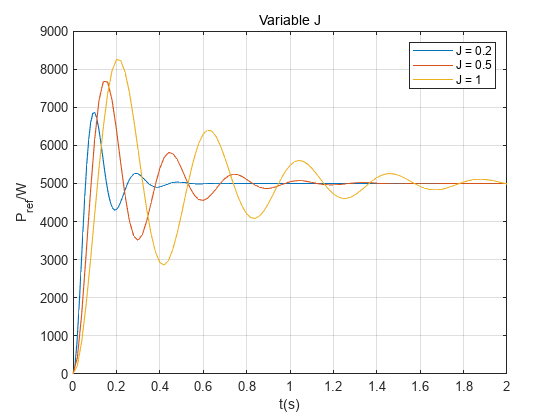

%test1: variable J
J = [0.2,0.5,1];
H = J*omega_0^2./S_n;
D_p = 8;
omega_n = sqrt(omega_0*S_E./H);
epu = 0.5*D_p*sqrt(1./(omega_0*S_E*H));
for i = 1:length(J)
    Gref2p = tf(omega_n(i).^2,[1 2*epu(i).*omega_n(i) omega_n(i).^2]);
    opt = RespConfig;
    opt.InputOffset = 0;
    opt.Amplitude = 5000;
    [y,t] = step(Gref2p,[0 2],opt);
    plot(t,y);
    hold on
end
hold off
grid on;
legend("J = 0.2","J = 0.5","J = 1");
xlabel("t(s)");
ylabel("P_{ref}/W")
title("Step response under variable J")

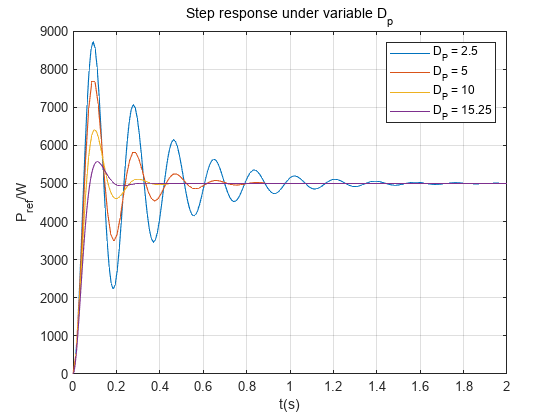


%test2: variable J
J = 0.2;%thesis typo
H = J*omega_0^2./S_n;
D_p = [2.5 5 10 15.25];
omega_n = sqrt(omega_0*S_E./H);
epu = 0.5.*D_p*sqrt(1./(omega_0*S_E*H));
for i = 1:length(D_p)
    Gref2p = tf(omega_n.^2,[1 2*epu(i).*omega_n omega_n.^2]);
    opt = RespConfig;
    opt.InputOffset = 0;
    opt.Amplitude = 5000;
    [y,t] = step(Gref2p,[0 2],opt);
    plot(t,y);
    hold on
end
hold off
grid on;
legend("D_P = 2.5","D_P = 5","D_P = 10","D_P = 15.25");
xlabel("t(s)");
ylabel("P_{ref}/W")
title("Step response under variable D_p")